% Plot graphs
Plot = false;
% Save praphs
Save_graph = true;

% Determine where your m-file's folder is
folder = fileparts(which("opt_problem.mlx"));
% Add that folder plus all subfolders to the path
addpath(genpath(folder));

#### GFDM parameters.

gfdm = struct;
%gfdm.K = 5; % Subcarriers
%gfdm.M = 5; % Subsymbols
gfdm.K = K;
gfdm.M = M;

gfdm.CP = 0; % CP length

SEM = "802.11ac";
Channel = 20; % Channel bandwidth (MHz)

uti_threshold =  0.55; % Utilize rate threshold

gfdm = GFDM_init(gfdm);

D = gfdm.D;

Normalized frequency $f$ and normalized frequency interval $\Delta f$

delta_f = 0.01;     % Normalized frequency: f = F/Fs = F/2B = F*Ts
f_range_end = 0.5;   % rc filter limit

% f_range_end should be divisible by delta_f
if mod(f_range_end,f_range_end)
    msg = 'normalized frequency sampling interval delta_f can not equally spaces f_range';
    error(msg);
end

f_range = [0 f_range_end];
f = -f_range(2):delta_f:f_range(2);

Interpolation filter $P(f)$

P = rc_filter(delta_f, f_range, 0.1);

All combinations of $K_{\textrm{on}}$ and $M_{\textrm{on}}$ with decreasing order: $N$

The number of element used $N_{\textrm{sort}} \left(n\right)$ is the result of using $K_{\textrm{on}}$ = $\textrm{sort}\_\textrm{idx}\_K\left(n\right)$ and $M_{\textrm{on}}$ = $\textrm{sort}\_\textrm{idx}\_M\left(n\right)$.

[N_sort, sort_idx_K, sort_idx_M] = sort_N(gfdm);

#### Find the maximum used resource $N$ and its corresponding $K_{\textrm{on}}$ and $M_{\textrm{on}}$.

% Start from the first index with utilize rate grater than the utilize rate
% threshold
uti_rate = N_sort/gfdm.D;
idx_start = find(uti_rate < uti_threshold, 1) - 1;

if idx_start < 2
    idx_start = 2;
end

feasible_count = 0; % Feasible set counter
K_on_set = zeros(1, 5);
M_on_set = zeros(1, 5);

% Loop used resources
N_counter = idx_start;
N_start = tic;

for n = idx_start:D
    % How many sets remain with the same utilize rate as the current one
    tie = numel(find(N_sort(N_counter:end) == N_sort(N_counter)));

    N = N_sort(n);
    gfdm.K_on = sort_idx_K(n); gfdm.M_on = sort_idx_M(n);
    fprintf("%d. K_on = %d M_on = %d N = %d \n", N_counter-idx_start+1, gfdm.K_on, gfdm.M_on, N);
    fprintf("Utilize rate: %f \n", N/D);

    S = Dottorro(gfdm, Channel, Channel, P, SEM, f_range, delta_f);

    % Feasible set found
    if ~isnan(S)
        feasible_count = feasible_count + 1;
        K_on_set(feasible_count) = gfdm.K_on;
        M_on_set(feasible_count) = gfdm.M_on;
    end

    % Break if there is no remaining set with the same utilize rate as the
    % feasible one
    if feasible_count~=0 && tie==1
        break;
    end

    N_counter = N_counter + 1;
end

K_on_set = K_on_set(1:feasible_count);
M_on_set = M_on_set(1:feasible_count);

fprintf('===============================\n');
fprintf("K_on = %s M_on = %s N = %d \n", join(string(K_on_set), ','), join(string(M_on_set), ','), N);
fprintf("Utilized rate: %f \n", N/D);
fprintf('Max utilization time: %s\n', duration([0, 0, toc(N_start)]));
fprintf('===============================\n');

#### Bisection method to find the max transmission bandwidth $B$.

B = zeros(size(K_on_set));
S_solved = zeros([gfdm.D, gfdm.D, numel(K_on_set)]);

for idx = 1:numel(K_on_set)
    gfdm.K_on = K_on_set(idx);
    gfdm.M_on = M_on_set(idx);

    % Bisection stop criteria
    B_low = Channel; % transmission bandwidth
    B(idx) = B_low;
    B_up = 2*Channel;
    B_criteria = 0.1;
    B_diff = B_criteria;
    B_mid = B_up;
    
    while B_diff >= B_criteria

#### Dottorro iterative algorithm & optimization problem


$$\mathbf{S}=\mathbf{g}\mathbf{g}^H$$


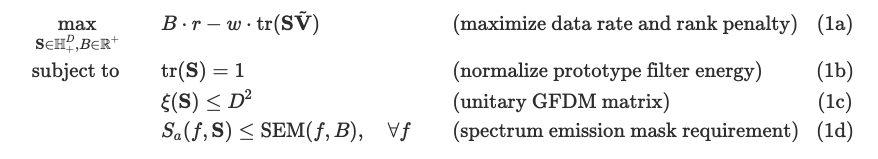

        S = Dottorro(gfdm, B_mid, Channel, P, SEM, f_range, delta_f);

        if isnan(S)
            % Bisection update if infeasible
            B_up = B_mid;
        else
            S_solved(:, :, idx) = S;

            % Bisection update if feasible
            B_low = B_mid;
            B(idx) = B_mid;

            if Plot == 1
                S_a_S = PSD_S(gfdm, S, psd_temp, f_range, delta_f);
                plot_PSD((P.^2) .* S_a_S, mask_linear, f_range);
            end

        end

        B_diff = B_up - B_low;
        % Midpoint
        B_mid = (B_up + B_low)/2;
    end
end

fprintf("K: %d M: %d B: %s \n",gfdm.K, gfdm.M, join(string(B), ','));
[max_B, idx] = max(B);
gfdm.K_on = K_on_set(idx);
gfdm.M_on = M_on_set(idx);

switch SEM
    case "802.11ac"
        mask_dB = SEM_ac(delta_f, f_range, max_B, Channel);
    case "802.11b"
        mask_dB = SEM_b(delta_f, f_range, max_B, Channel);
end
mask_linear = db2pow(mask_dB);
psd_temp = zeros(size(P));
% g = S2g(S); G = g2chaG(g, gfdm.K, gfdm.M);
% S_a = PSD_G(gfdm, G, f_range, delta_f);
S_a_S = PSD_S(gfdm, S_solved(:, :, idx), psd_temp, f_range, delta_f);

if Save_graph
    save_PSD(gfdm, (P.^2) .* S_a_S, mask_linear, f_range, max_B);
end

if Plot
     
    plot_PSD(gfdm, (P.^2) .* S_a_S, mask_linear, f_range, max_B);
end

% to open the figure 
% openfig('newout.fig','new','visible')